% a clear MATLAB workspace is a clear mental workspace
close all; clear

## create data for the plot

nbins = 5;
totalN = 100;

% You would have a distribution of 1-5 and then you ceil them so you can
% categorize or make it into a "nominal"
rawdata = ceil(logspace(log10(1/2),log10(nbins-.01),totalN));

% prepare data for pie chart
uniquenums = unique(rawdata);
data4pie = zeros(length(uniquenums),1);

for i=1:length(uniquenums)
    data4pie(i) = sum(rawdata==uniquenums(i));
end

## show the pie chart

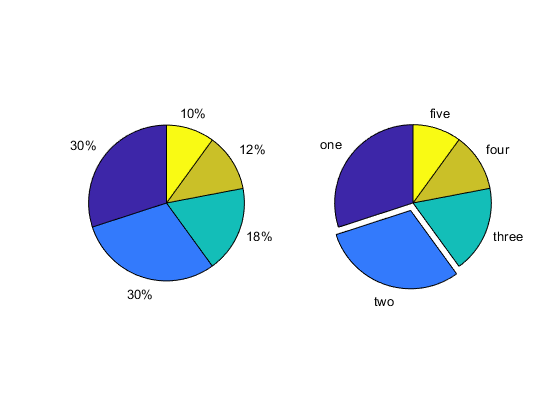

figure(1), clf

subplot(121)
pie(data4pie)

subplot(122)
pie(data4pie,[0 1 0 0 0],{'one','two','three','four','five'})

## for continuous data

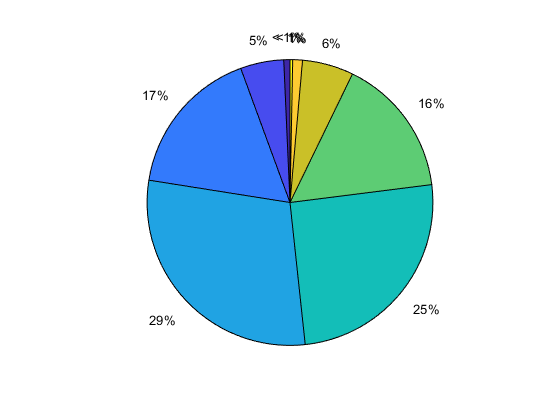

% generate log-normal distribution
data = exp( randn(1000,1)/10 );


figure(2), clf

% generate bins using histogram
histbins = histcounts(data,9);

% and show that as a pie chart
pie(histbins)

## done.